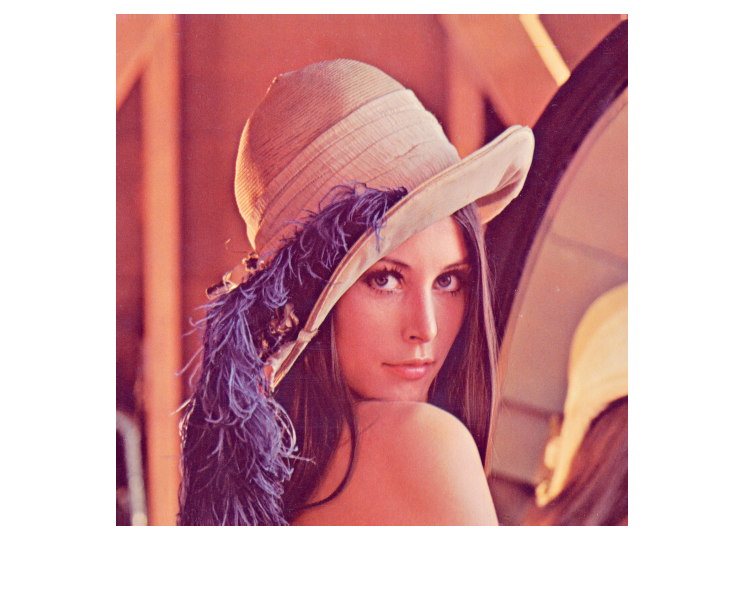

clear;clf;
src = imread("../images/lena_color.tif");
target = imread("../images/PeppersRGB.tif");
imshow(src)

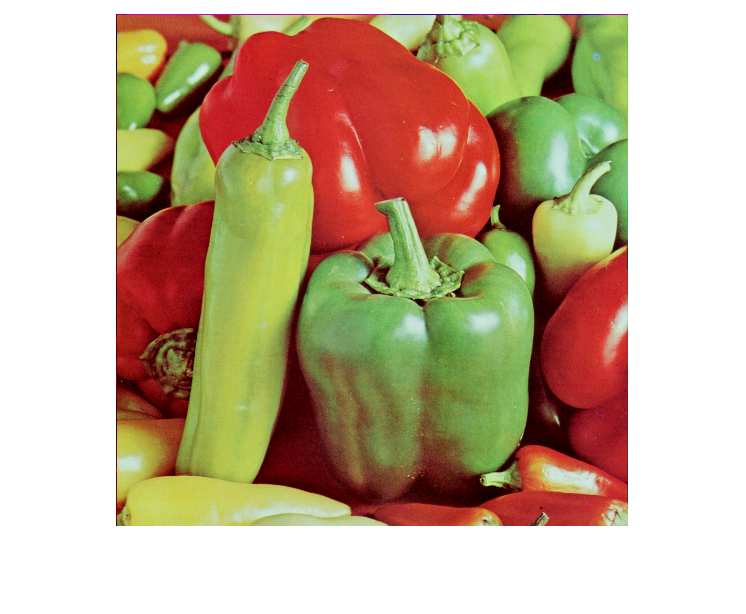

imshow(target)

hist_src = zeros(3, 256);
hist_target = zeros(3, 256);
dist_src = zeros(3, 256);
dist_target = zeros(3, 256);
for i = 1:3
    for j = 0:255
%         count histogram for src and target images channel-wise.
        hist_src(i, j+1) = sum(sum(src(:, :, i) == j));
        hist_target(i, j+1) = sum(sum(target(:, :, i) == j));
    end
    dist_src(i,:) = hist_src(i,:) / sum(hist_src(i,:));
    dist_target(i,:) = hist_target(i,:) / sum(hist_target(i,:));
end

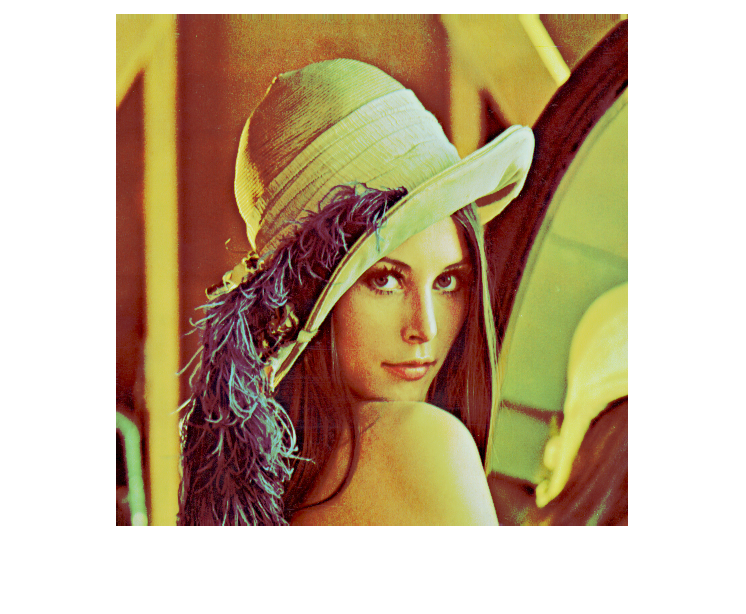

s2u_map = zeros(3, 256); % src to uniform map
t2u_map = zeros(3, 256); % target to uniform map

result = zeros(size(src));

for i = 1:3
    prefix_sum_s = 0;
    prefix_sum_t = 0;
    
    result_slice = result(:, :, i);

    for j = 0:255
        prefix_sum_s = prefix_sum_s + dist_src(i, j+1);
        prefix_sum_t = prefix_sum_t + dist_target(i, j+1);
        s2u_map(i, j+1) = round(255 * prefix_sum_s);
        t2u_map(i, j+1) = round(255 * prefix_sum_t);
    end

    for j = 0:255
        map_idx = find(t2u_map(i, :) == s2u_map(i, j+1), 1);
        offset = 1;
%         if no exactly mapping found, find the nearest one
        while isempty(map_idx)
            left = s2u_map(i, j+1) - offset;
            right = s2u_map(i, j+1) + offset;

            if right <= 255
                right_idx = find(t2u_map(i, :) == right, 1, 'first');
                if ~isempty(right_idx)
                    map_idx = right_idx;
                end
            end
%           if the left and the right have the same distance, the left idx
%           has higher priority.
            if left >= 0
                left_idx = find(t2u_map(i, :) == left, 1, 'last');
                if ~isempty(left_idx)
                    map_idx = left_idx;
                end
            end  
            
            if left < 0 && right > 255
                break
            end

            offset = offset + 1;
        end
        result_slice(src(:, :, i) == j) = map_idx;
        result(:, :, i) = result_slice;   
    end
end

imshow(uint8(result))